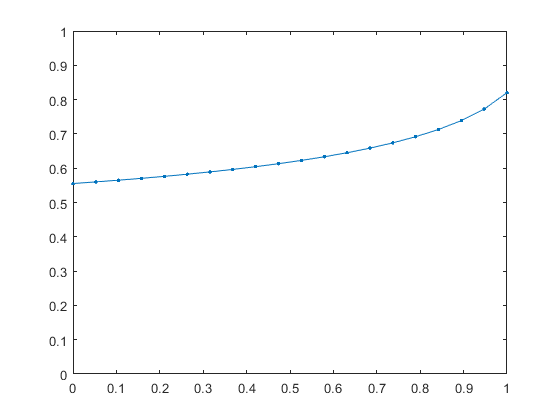


%% reducing the number of symbolic commands in the expression
d1_max = 0.8; % dose proportion to EC50
d2_max = 0.6; % dose proportion to EC50


d1 = linspace(0.001, d2_max, 20);
d2 = linspace(d1_max, 0.001, 20);

a = 0;

y = test(d1, d2, a);
y = real(y);
plotaxis = linspace(0, 1, length(d1));
plot(plotaxis, y, '.-')
axis([0 1 0 1])




% actual function space


function y = test(d_1, d_2, a)
% a is interaction index from Greco et al. 1995
for i = 1:length(d_1)
ED50_1 = 1;
ED50_2 = 1;
E0 = 1;
Emax = 0;
h1 = 3;
h2 = 1;
d1 = d_1(i);
d2 = d_2(i);

% greco 1995 model, formulation of G L Drusano et al
syms E
termA = (d1 ./ (ED50_1 .* ((E - E0) ./ (Emax - E)).^ (1./h1)));
termB = (d2 ./ (ED50_2 .* ((E - E0) ./ (Emax - E)).^ (1./h2)));
termC = a .* d1 .* d2;
termD = ED50_1 .* ED50_2 .* ((E - E0) ./ (Emax - E)) .^ ((1 ./ (2 .* h1)) + (1 ./ (2 .* h2)));
equation = termA + termB + (termC ./ termD); % -1 to solve for equal to 0

test = vpasolve(equation == 1, E);
y(i) = eval(subs(test));

end % end of i loop
end % end of function
%test4 = vpasolve(equation == 1, E);
%y2 = eval(subs(test4));


% notes
% currently works for the vpasolve implementation of just d1
% trying to do this with the implementation for the entire equation